# 数字信号处理课程设计——抽取

clc;clear sound;close all;

### 读取音频

Fs=44100;
T_start=0.01;
T_end=2.4;
interval=T_end-T_start;
multi=30;
music=audioread("媒体1.wav",round([T_start*Fs,T_end*Fs]));
% music=audioread("The Truth That You Leave.mp3",round([T_start*Fs,T_end*Fs]));
music=music(:,1)';
lenm=ceil(length(music)/multi);
music=[music,zeros(1,lenm*multi-length(music))];
% audioinfo("The Truth That You Leave.mp3")

### 使用resample函数

disp('使用resample函数抽取用时')

使用resample函数抽取用时


tic
y1=Resample_D(music,multi);
toc

历时 0.189338 秒。


### 直接抽取

disp('直接抽取用时')

直接抽取用时


tic
y2=DirectDecimation(music,multi);
toc

历时 0.003029 秒。


### 先滤波后抽取

disp('直接卷积后抽取用时')

直接卷积后抽取用时


tic
y3=Convolution_D(music,multi);
toc

历时 0.065318 秒。


### 多相结构

disp('多相滤波抽取用时')

多相滤波抽取用时


tic
y4=PolyphaseFilter_D(music,multi);
toc

历时 0.014231 秒。


### 观察频谱

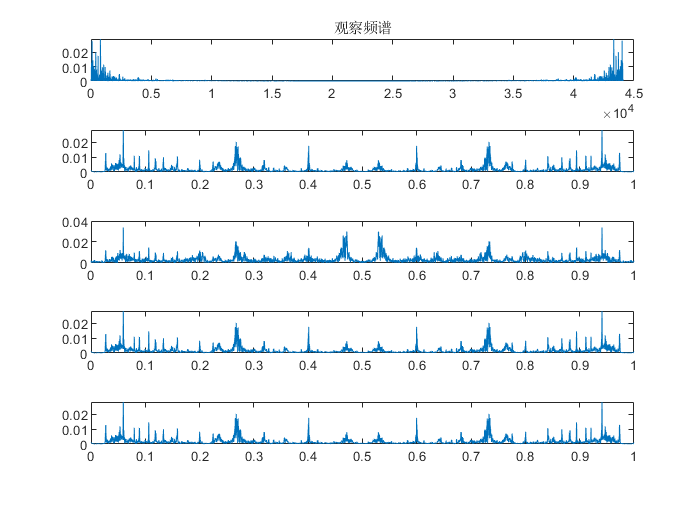

t=1:length(y1);
t=t./Fs.*multi;
w=t./length(y1).*Fs./multi;
figure(1)
subplot(511)
plot((1:length(music)).*Fs./length(music),abs(fft(music))/length(music));
title('观察频谱')
subplot(512)
plot(w,abs(fft(y1))/length(y1));
subplot(513)
plot(w,abs(fft(y2))/length(y2));
subplot(514)
plot(w,abs(fft(y3))/length(y3));
subplot(515)
plot(w,abs(fft(y4))/length(y4));


% figure(1)
% subplot(511)
% plot((1:length(music)).*Fs./length(music),fftshift(abs(fft(music)))/length(music));
% title('观察频谱')
% subplot(512)
% plot(t,fftshift(abs(fft(y1)))/length(y1));
% subplot(513)
% plot(t,fftshift(abs(fft(y2)))/length(y2));
% subplot(514)
% plot(t,fftshift(abs(fft(y3)))/length(y3));
% subplot(515)
% plot(t,fftshift(abs(fft(y4)))/length(y4));

### 观察时域波形

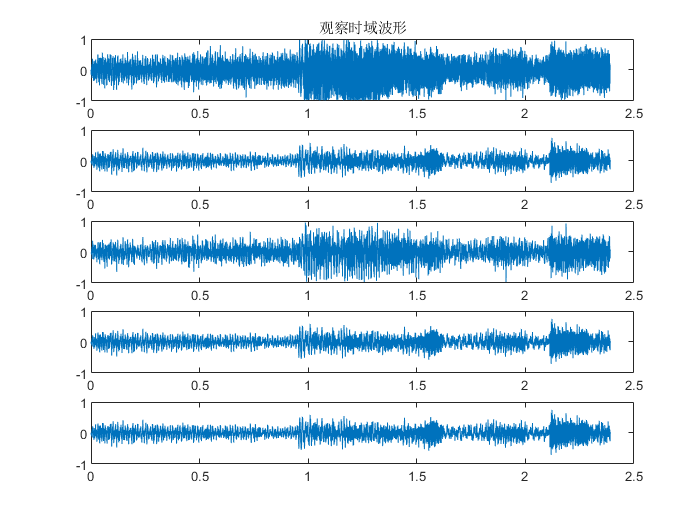

figure(2)
subplot(511)
plot((1:length(music))./Fs,music);
title('观察时域波形')
subplot(512)
plot(t,y1);
subplot(513)
plot(t,y2);
subplot(514)
plot(t,y3);
subplot(515)
plot(t,y4);

### 播放音频

% sound(music,Fs)
% pause(interval)
% sound(y1,round(Fs/multi))
% pause(interval)
% sound(y2,round(Fs/multi))
% pause(interval)
% sound(y3,round(Fs/multi))
% pause(interval)
% sound(y4,round(Fs/multi))
% pause(interval)

### 计算信噪比

disp('计算信噪比：')

计算信噪比：


s=sum(y1.^2);
sig21=sum((y2-y1).^2);SNR2=10*log10(s/sig21)

SNR2 = -0.9531

sig31=sum((y3-y1).^2);SNR3=10*log10(s/sig31)

SNR3 = 63.4268

sig41=sum((y4-y1).^2);SNR4=10*log10(s/sig41)

SNR4 = 63.4268

disp(['SNR3-SNR2=',num2str(SNR3-SNR2)])

SNR3-SNR2=64.3798


disp(['|SNR3-SNR4|=',num2str(abs(SNR3-SNR4))])

|SNR3-SNR4|=1.1013e-12
